## Set up

clc
clear
clf
rng(16);
PCA_components = 6;
UCL_conseq = 3;

## Preprocessing

SS.data = readtable('process_model\generated_data_take2\training\Noisy\measured_data_combined.csv');

SS.features = [SS.data.c_LO_measured SS.data.c_RE_measured SS.data.f_PLSP_measured SS.data.f_PLSS_measured SS.data.f_LO_measured SS.data.f_LE_measured SS.data.c_PLS_measured SS.data.c_LE_measured SS.data.c_RaffP_measured SS.data.c_RaffS_measured SS.data.c_BO_measured];
SS.means = mean(SS.features,1);
SS.devs = std(SS.features,1);
SS.time = SS.data.Time;

% normalize
for i = 1:size(SS.features,2)
    SS.X(:,i) = (SS.features(:,i) - SS.means(i))/(SS.devs(i));
end

## Perform PCA

[SS.loadings, SS.scores, PCA_latent_SS, PCA_tsquared_SS, PCA_explained_SS, PCA_mu_SS] = pca(SS.X);


### Setup plotting

% Line styles
line_width = 0.8;

% Colours
blue  = '#06ACE9';
white = '#FFFFFF';

### Scree plot

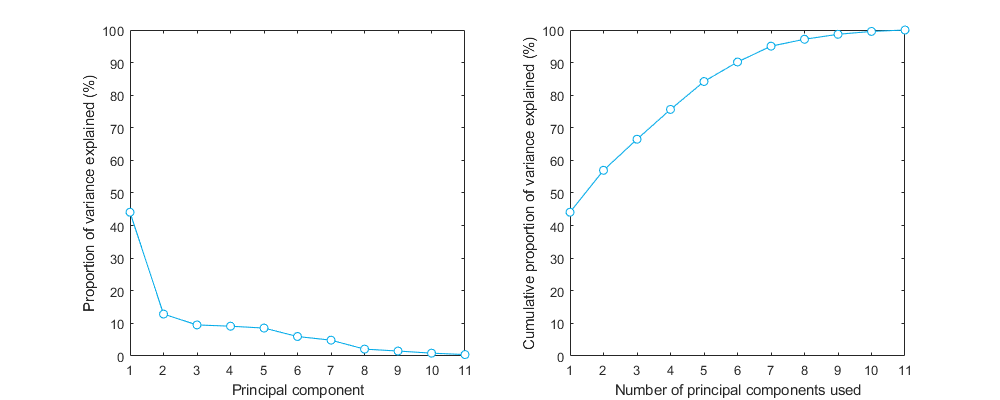

% Create the scree plot figure
figure()

% Plot the proportion of variance explained
subplot(1,2,1)
plot(PCA_explained_SS, '-o', 'LineWidth',line_width, 'Color', blue, 'MarkerFaceColor', white, 'MarkerEdgeColor', blue, 'MarkerSize', 6)
ylabel("Proportion of variance explained (%)")
xlabel("Principal component")
ylim([0 100])
xlim([1 11])
xticks([1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11])

% Plot the cumulative proportion of variance explained
subplot(1,2,2)
plot(cumsum(PCA_explained_SS), '-o', 'LineWidth',line_width, 'Color', blue, 'MarkerFaceColor', white, 'MarkerEdgeColor', blue, 'MarkerSize', 6)
ylabel("Cumulative proportion of variance explained (%)")
xlabel("Number of principal components used")
ylim([0 100])
xlim([1 11])
xticks([1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11])

% Set the plot size
fig_scree_plot = gcf;
fig_scree_plot.Position(3:4) = [1000, 400];

### PCA loadings

% Variable labels
measured_variable_labels = categorical({'c_{LO}', 'c_{RE}', 'f_{PLSP}', 'f_{PLSS}', 'f_{LO}', 'f_{LE}', 'c_{PLS}', 'c_{LE}', 'c_{RaffP}', 'c_{RaffS}', 'c_{BO}'});
measured_variable_labels = reordercats(measured_variable_labels, {'c_{LO}', 'c_{RE}', 'f_{PLSP}', 'f_{PLSS}', 'f_{LO}', 'f_{LE}', 'c_{PLS}', 'c_{LE}', 'c_{RaffP}', 'c_{RaffS}', 'c_{BO}'});

### Principal component 1

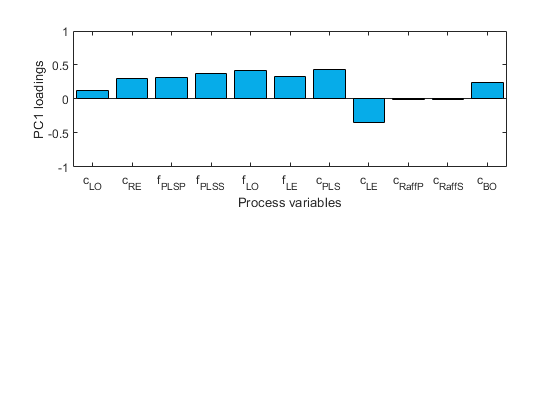

% Create the figure for the 1st principal component
figure()

% Plot the proportion of variance explained
subplot(2,1,1)
bar(measured_variable_labels, SS.loadings(:,1), 'FaceColor', blue)
ylabel('PC1 loadings')
xlabel('Process variables')
ylim([-1 1])

### Principal component 2

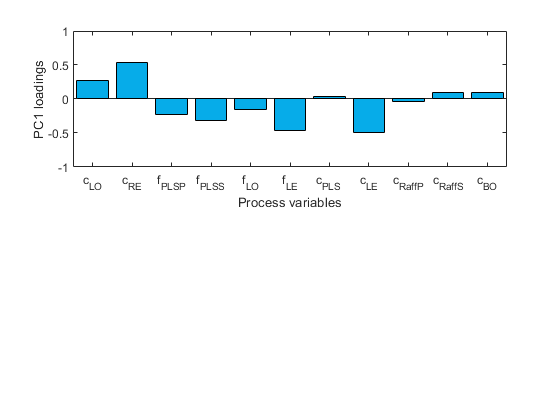

% Create the figure for the 2nd principal component
figure()

% Plot the proportion of variance explained
subplot(2,1,1)
bar(measured_variable_labels, SS.loadings(:,2), 'FaceColor', blue)
ylabel('PC1 loadings')
xlabel('Process variables')
ylim([-1 1])

### Principal component 3

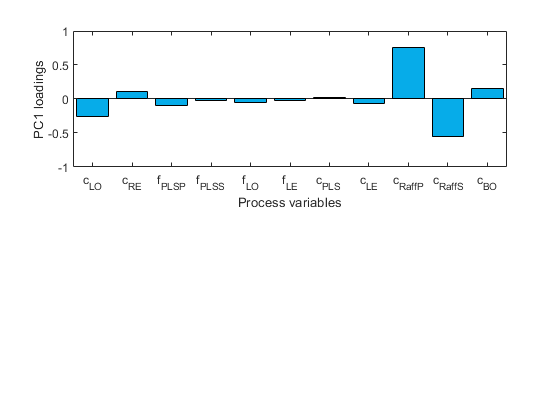

% Create the figure for the 3rd principal component
figure()

% Plot the proportion of variance explained
subplot(2,1,1)
bar(measured_variable_labels, SS.loadings(:,3), 'FaceColor', blue)
ylabel('PC1 loadings')
xlabel('Process variables')
ylim([-1 1])

### Principal component 4

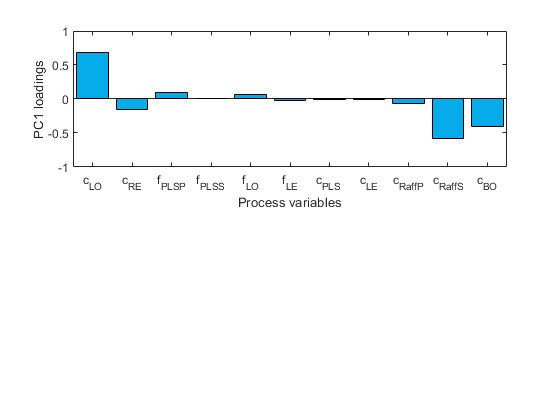

% Create the figure for the 4th principal component
figure()

% Plot the proportion of variance explained
subplot(2,1,1)
bar(measured_variable_labels, SS.loadings(:,4), 'FaceColor', blue)
ylabel('PC1 loadings')
xlabel('Process variables')
ylim([-1 1])

### Principal component 5

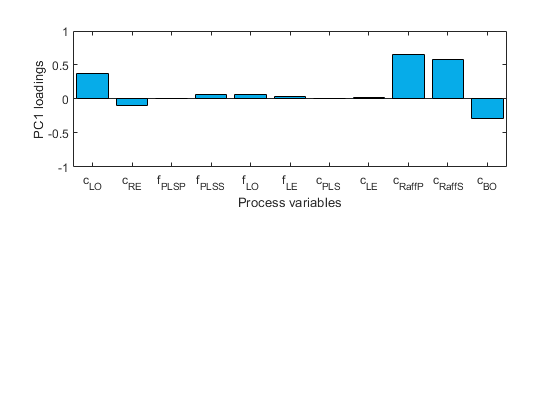

% Create the figure for the 5th principal component
figure()

% Plot the proportion of variance explained
subplot(2,1,1)
bar(measured_variable_labels, SS.loadings(:,5), 'FaceColor', blue)
ylabel('PC1 loadings')
xlabel('Process variables')
ylim([-1 1])

### Principal component 6

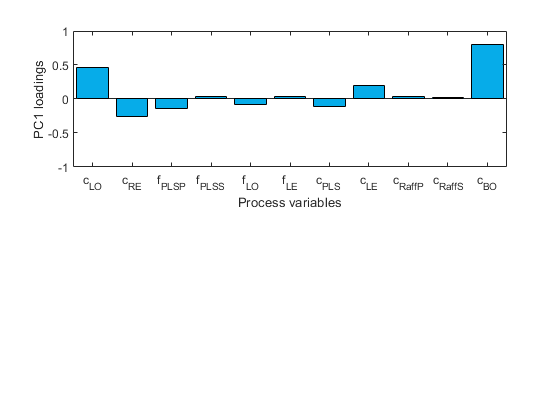

% Create the figure for the 6th principal component
figure()

% Plot the proportion of variance explained
subplot(2,1,1)
bar(measured_variable_labels, SS.loadings(:,6), 'FaceColor', blue)
ylabel('PC1 loadings')
xlabel('Process variables')
ylim([-1 1])

### Principal component 7

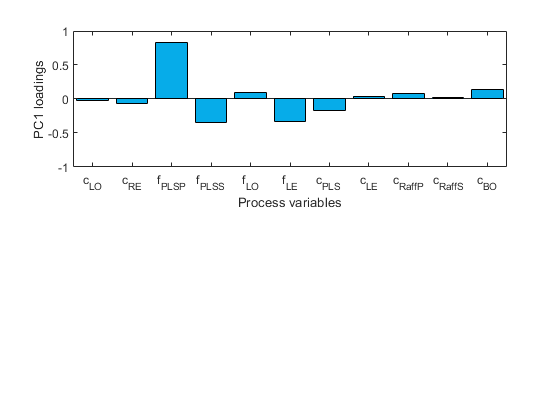

% Create the figure for the 7th principal component
figure()

% Plot the proportion of variance explained
subplot(2,1,1)
bar(measured_variable_labels, SS.loadings(:,7), 'FaceColor', blue)
ylabel('PC1 loadings')
xlabel('Process variables')
ylim([-1 1])

### Principal component 8

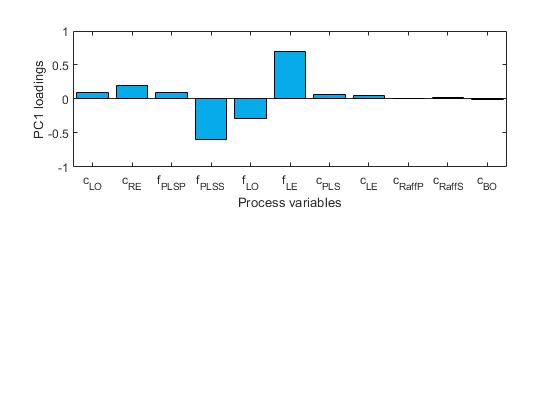

% Create the figure for the 8th principal component
figure()

% Plot the proportion of variance explained
subplot(2,1,1)
bar(measured_variable_labels, SS.loadings(:,8), 'FaceColor', blue)
ylabel('PC1 loadings')
xlabel('Process variables')
ylim([-1 1])

### Principal component 9

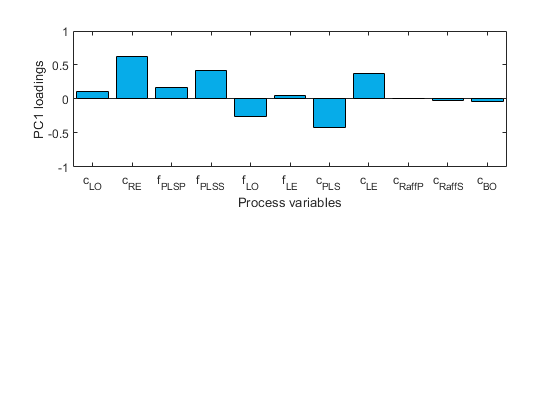

% Create the figure for the 9th principal component
figure()

% Plot the proportion of variance explained
subplot(2,1,1)
bar(measured_variable_labels, SS.loadings(:,9), 'FaceColor', blue)
ylabel('PC1 loadings')
xlabel('Process variables')
ylim([-1 1])

### Principal component 10

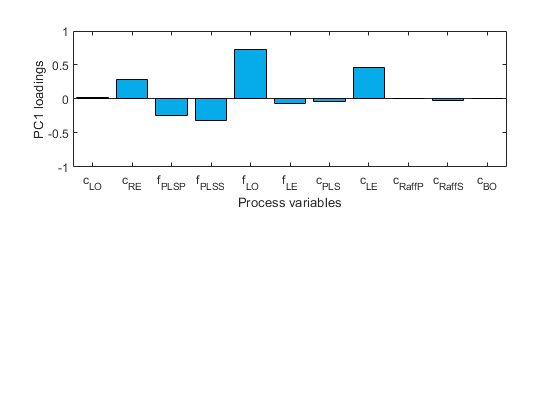

% Create the figure for the 10th principal component
figure()

% Plot the proportion of variance explained
subplot(2,1,1)
bar(measured_variable_labels, SS.loadings(:,10), 'FaceColor', blue)
ylabel('PC1 loadings')
xlabel('Process variables')
ylim([-1 1])

### Principal component 11

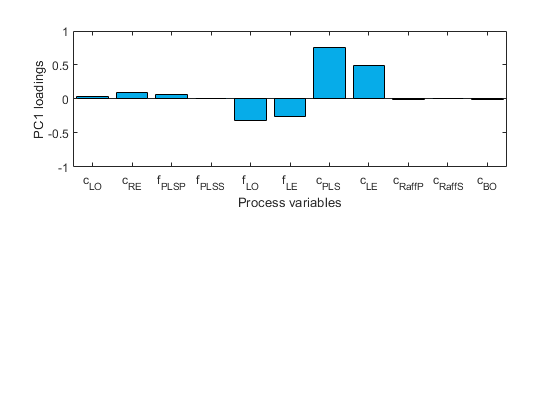

% Create the figure for the 11th principal component
figure()

% Plot the proportion of variance explained
subplot(2,1,1)
bar(measured_variable_labels, SS.loadings(:,11), 'FaceColor', blue)
ylabel('PC1 loadings')
xlabel('Process variables')
ylim([-1 1])

## Reduce PCA 

% % singular value matrix
% SIGMA = diag(PCA_latent_SS);
% SIGMA_inv = inv(SIGMA);
% 
% % reduced matrices
% SIGMA_reduced = diag(PCA_latent_SS(1:PCA_components));
% SIGMA_reduced_inv = inv(SIGMA_reduced);
% PCA_loadings_reduced = SS.loadings(:, 1:PCA_components);
% scores_reduced = SS.scores(:, 1:PCA_components);
% 
% % reconstruct PCA data 
% SS.X_subspace = scores_reduced*PCA_loadings_reduced';
% SS.X_residual = SS.X - SS.X_subspace;

## Hotelling T2 

% for i = 1:PCA_components
%     SS.tsq(:,i) = SIGMA_reduced_inv(i,i)*(scores_reduced(:,i).^2);
% end
% SS.Tsq = sum(SS.tsq,2);
% T_thresh = max(SS.Tsq)*0.5;

## Q statistic 

% for i = 1:size(SS.features,2)
%     SS.q(:,i) = SS.X_residual(:,i).^2;
% end
% SS.Q = sum(SS.q,2);
% Q_thresh = max(SS.Q)*0.5;

### Training control chart

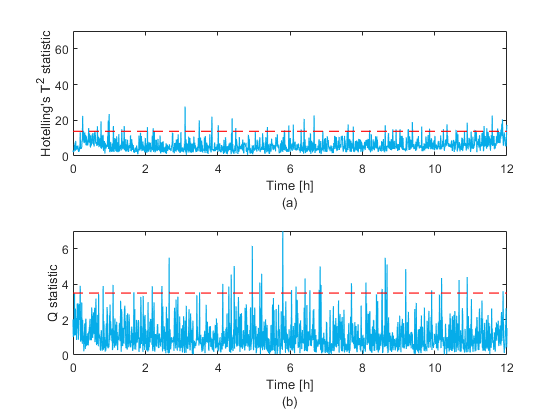

% % Create the figure for the training control charts
% figure()
% 
% % Plot the training Hotelling's T2 statistic
% subplot(2,1,1)
% plot(SS.time/(60*60), SS.Tsq, '-', 'Color', blue, 'LineWidth',line_width)
% hold on
% plot([0 SS.time(end)/(60*60)], [T_thresh T_thresh], '--r', 'LineWidth',line_width)
% hold off
% ylabel("Hotelling's T^{2} statistic")
% xlabel(["Time [h]", "(a)"])
% ylim([0, 70])
% 
% % Plot the training Q statistic
% subplot(2,1,2)
% plot(SS.time/(60*60), SS.Q, '-', 'Color', blue, 'LineWidth',line_width)
% hold on
% plot([0 SS.time(end)/(60*60)], [Q_thresh Q_thresh], '--r', 'LineWidth',line_width)
% hold off
% ylabel("Q statistic")
% xlabel(["Time [h]", "(b)"])
% ylim([0, 7])

## Training Hotelling T2

% T2_alarm_train = zeros(length(SS.time),1);
% conseq_T2_alarm = 0;
% 
% for i = 1:length(SS.time)
%     if(SS.Tsq(i) > T_thresh)
%         if(conseq_T2_alarm == UCL_conseq)
%             T2_alarm_train(i) = 1;
%         else
%             T2_alarm_train(i) = 0;
%             conseq_T2_alarm = conseq_T2_alarm +1;
%         end
%     else
%         T2_alarm_train(i) = 0;
%         conseq_T2_alarm = 0;
%     end
% end

## Training Q Stat

% Q_alarm_train = zeros(length(SS.time),1);
% conseq_Q_alarm = 0;
% 
% for i = 1:length(SS.time)
%     if(SS.Q(i) > Q_thresh)
%         if(conseq_Q_alarm == UCL_conseq)
%             Q_alarm_train(i) = 1;
%         else
%             Q_alarm_train(i) = 0;
%             conseq_Q_alarm = conseq_Q_alarm +1;
%         end
%     else
%         Q_alarm_train(i) = 0;
%         conseq_Q_alarm = 0;
%     end
% end

### Training fault detection

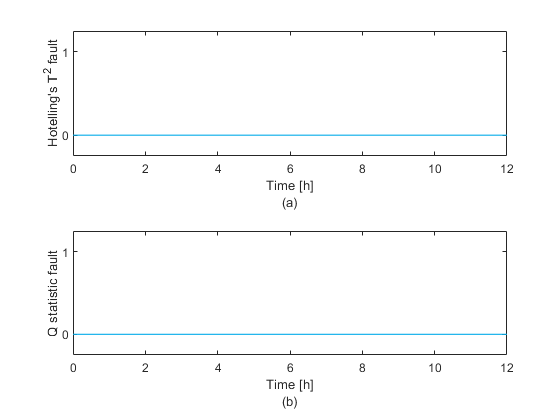

% % Create the figure for the training fault detection
% figure()
% 
% % Plot the Hotelling's T2 fault detection
% subplot(2,1,1)
% plot(SS.time/(60*60), T2_alarm_train, 'Color', blue,'LineWidth', line_width)
% ylabel("Hotelling's T^{2} fault")
% xlabel(["Time [h]", "(a)"])
% ylim([-0.25 1.25])
% yticks([0, 1]) 
% 
% % Plot the Q statistic fault detection
% subplot(2,1,2)
% plot(SS.time/(60*60), Q_alarm_train, 'Color', blue,'LineWidth', line_width)
% ylabel("Q statistic fault")
% xlabel(["Time [h]", "(b)"])
% ylim([-0.25 1.25])
% yticks([0, 1]) 

## Faulty Data

### Preprocessing

% F.data = readtable('toy_problem\generated_data\training\PS_2_0.5Days\data\measured_data.csv');
% 
% F.features = [F.data.c_LO_measured F.data.c_RE_measured F.data.f_PLSP_measured F.data.f_PLSS_measured F.data.f_LO_measured F.data.f_LE_measured F.data.c_PLS_measured F.data.c_LE_measured F.data.c_RaffP_measured F.data.c_RaffS_measured F.data.c_BO_measured];
% F.means = mean(F.features,1);
% F.devs = std(F.features,1);
% F.time = F.data.Time;
% 
% % normalize
% for i = 1:size(F.features,2)
%     F.X(:,i) = (F.features(:,i) - F.means(i))/(F.devs(i));
% end

### Hotelling T2

% F.scores = F.X*SS.loadings(:,1:PCA_components);
% 
% for i = 1:PCA_components
%     F.tsq(:,i) = SIGMA_reduced_inv(i,i)*(F.scores(:,i).^2);
% end
% F.Tsq = sum(F.tsq,2);

### Q statistic 

% F.X_residual = F.X - F.scores*PCA_loadings_reduced';
% for i = 1:size(SS.features,2)
%     F.q(:,i) = F.X_residual(:,i).^2;
% end
% F.Q = sum(F.q,2);

### Fault detection control chart

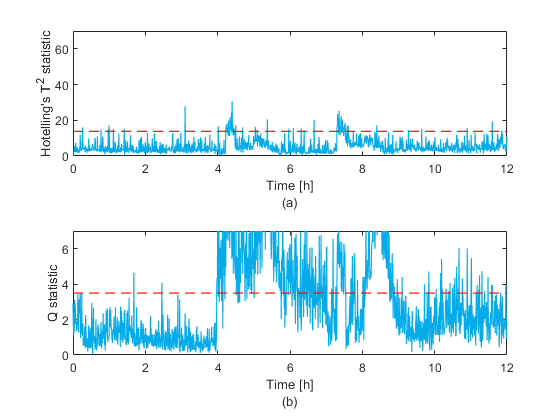

% % Create the figure for the training control charts
% figure()
% 
% % Plot the training Hotelling's T2 statistic
% subplot(2,1,1)
% plot(F.time/(60*60), F.Tsq, '-', 'Color', blue, 'LineWidth',line_width)
% hold on
% plot([0 F.time(end)/(60*60)], [T_thresh T_thresh], '--r', 'LineWidth',line_width)
% hold off
% ylabel("Hotelling's T^{2} statistic")
% xlabel(["Time [h]", "(a)"])
% ylim([0, 70])
% 
% % Plot the training Q statistic
% subplot(2,1,2)
% plot(F.time/(60*60), F.Q, '-', 'Color', blue, 'LineWidth',line_width)
% hold on
% plot([0 F.time(end)/(60*60)], [Q_thresh Q_thresh], '--r', 'LineWidth',line_width)
% hold off
% ylabel("Q statistic")
% xlabel(["Time [h]", "(b)"])
% ylim([0, 7])

### Fault detection Hotelling T2

% T2_alarm_fault = zeros(length(F.time),1);
% conseq_T2_alarm = 0;
% 
% for i = 1:length(F.time)
%     if(F.Tsq(i) > T_thresh)
%         if(conseq_T2_alarm == UCL_conseq)
%             T2_alarm_fault(i) = 1;
%         else
%             T2_alarm_fault(i) = 0;
%             conseq_T2_alarm = conseq_T2_alarm +1;
%         end
%     else
%         T2_alarm_fault(i) = 0;
%         conseq_T2_alarm = 0;
%     end
% end

### Fault detection Q Stat

% Q_alarm_fault = zeros(length(F.time),1);
% conseq_Q_alarm = 0;
% 
% for i = 1:length(F.time)
%     if(F.Q(i) > Q_thresh)
%         if(conseq_Q_alarm == UCL_conseq)
%             Q_alarm_fault(i) = 1;
%         else
%             Q_alarm_fault(i) = 0;
%             conseq_Q_alarm = conseq_Q_alarm +1;
%         end
%     else
%         Q_alarm_fault(i) = 0;
%         conseq_Q_alarm = 0;
%     end
% end

### Fault detection's fault detection

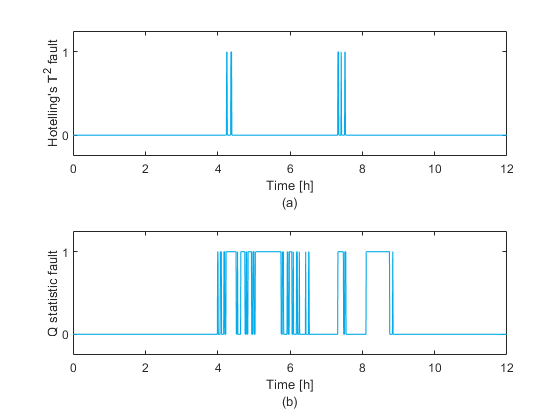

% % Create the figure for the Fault detection fault detection
% figure()
% 
% % Plot the Hotelling's T2 fault detection
% subplot(2,1,1)
% plot(F.time/(60*60), T2_alarm_fault, 'Color', blue,'LineWidth', line_width)
% ylabel("Hotelling's T^{2} fault")
% xlabel(["Time [h]", "(a)"])
% ylim([-0.25 1.25])
% yticks([0, 1]) 
% 
% % Plot the Q statistic fault detection
% subplot(2,1,2)
% plot(F.time/(60*60), Q_alarm_fault, 'Color', blue,'LineWidth', line_width)
% ylabel("Q statistic fault")
% xlabel(["Time [h]", "(b)"])
% ylim([-0.25 1.25])
% yticks([0, 1]) 

## ROC Curves

% F.fault_flag = F.data.fault_2_state;
% 
% % True states
% F.fault_count = sum(F.fault_flag == 1);
% F.normal_count = sum(F.fault_flag == 0);

### Hotelling T2

% F.T2_TP_count = 0;
% F.T2_FP_count = 0;
% for i = 1:length(F.time)
%     if(T2_alarm_fault(i) == 1)
%         if (F.fault_flag(i) == 1)
%             F.T2_TP_count = F.T2_TP_count + 1;
%         else
%             F.T2_FP_count = F.T2_FP_count + 1;
%         end
%     end
% end
% F.T2_TP_rate = F.T2_TP_count/F.fault_count; % Sensitivity
% F.T2_FP_rate = F.T2_FP_count/F.normal_count; % 1 - Specificity 

### Q stat

% F.Q_TP_count = 0;
% F.Q_FP_count = 0;
% for i = 1:length(F.time)
%     if(Q_alarm_fault(i) == 1)
%         if (F.fault_flag(i) == 1)
%             F.Q_TP_count = F.Q_TP_count + 1;
%         else
%             F.Q_FP_count = F.Q_FP_count + 1;
%         end
%     end
% end
% F.Q_TP_rate = F.Q_TP_count/F.fault_count; % Sensitivity
% F.Q_FP_rate = F.Q_FP_count/F.normal_count; % 1 - Specificity 

### Combined

% combined_alarm = zeros(length(F.time));
% 
% for i = 1:length(F.time)
%     if((T2_alarm_fault(i) == 1) || (Q_alarm_fault(i) == 1))
%         combined_alarm(i) = 1;
%     end
% end
% 
% F.combined_TP_count = 0;
% F.combined_FP_count = 0;
% for i = 1:length(F.time)
%     if(combined_alarm(i) == 1)
%         if (F.fault_flag(i) == 1)
%             F.combined_TP_count = F.combined_TP_count + 1;
%         else
%             F.combined_FP_count = F.combined_FP_count + 1;
%         end
%     end
% end
% F.combined_TP_rate = F.combined_TP_count/F.fault_count; % Sensitivity
% F.combined_FP_rate = F.combined_FP_count/F.normal_count; % 1 - Specificity 